# PSET 2

## Problem 1: Estimating the LIF Parameters

- We can find the leak potential by looking at the graph of the voltage of a neuron. Below is a graph of the voltage of the neuron with an input current of 0.5 nA. The graph was plotted using the code below:

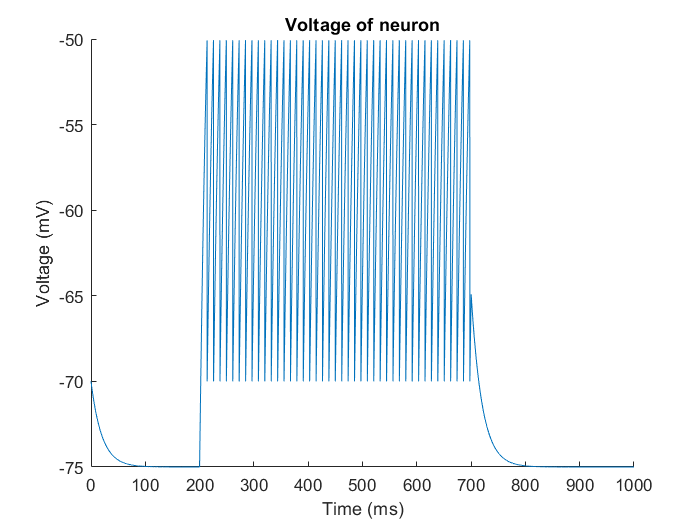

[V, I, t, spikeTimes] = LIFmodel(0.5); %Run the LIF Model given for an input current of 0.5 nA
plot(t,V)
xlabel('Time (ms)');
ylabel('Voltage (mV)');
title('Voltage of neuron');
box off

The voltage before the current starts at 2000 ms, is at -75 mV. Thus, our E_L = **- 75 mV.**

2. The threshold voltage is where the membrane potential hyperpolarizes and resets to the membrane resting voltage. We can see from the above graph that the voltage resets at -50 mV (we can see that from the fact that the highest point on the graph is at -50 mV). Thus our threshold voltage is **-50 mV**.

3. We can also see from the graph in 1-1 that every time the membrane voltage resets, it seems to reset to a voltage of -70 mV (bottom of the spike). Thus the reset voltage is **-70 mV**.

4. To find the resistance, we will need to set the Vinf to be less than the threshold voltage, and see what it is. We thus use the following code:

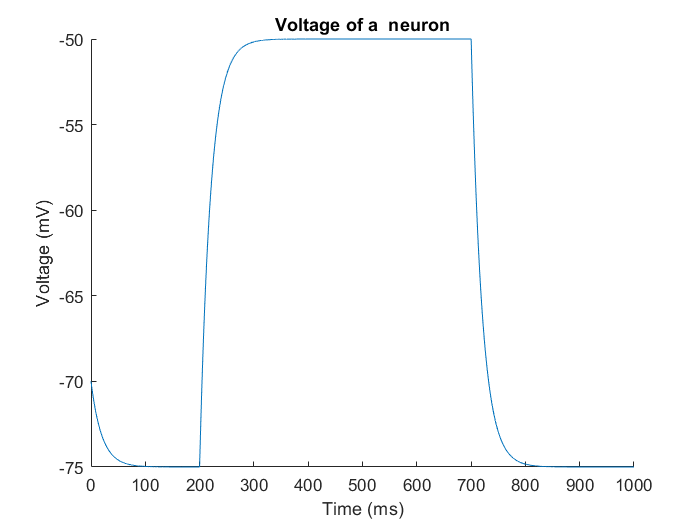

[V, I, t, spikeTimes] = LIFmodel(0.25); %Run the LIF Model for a given input current of 0.25 nA
plot(t,V)
xlabel('Time (ms)');
ylabel('Voltage (mV)');
title('Voltage of a  neuron');
box off

We see that this gives us that for an input current of 0.25 nA, the Vinf = -50 mV. We know that:


$$\begin{array}{l}
V_{\infty } =E_L +R_m \ast I_e \\
=-50\text{ }\mathrm{mV}=-75\text{ }\mathrm{mV}+R\ast \left(0\ldotp 25\ast {10}^{-9} \text{ }A\right)\\
=25\text{ }\mathrm{mV}=R_m \ast \left(0\ldotp 25\ast {10}^{-9} \text{ }A\right)\\
=R_m =\frac{\ldotp 025\text{ }V}{0\ldotp 25\ast {10}^{-9} }=1\ast {10}^8 \text{ }\Omega =1\ast {10}^2 \text{ }M\Omega 
\end{array}$$


5. The voltage will reach 1-(1/e) of the way to the Vinf by the time one time constant (tau) has passed. We can estimate this with the above graph as:


$$\begin{array}{l}
\left(1-\frac{1}{e}\right)\ast \left(-50\text{ }\mathrm{mV}--75\text{ }\mathrm{mV}\right)=0\ldotp 632\ast \left(25\text{ }\mathrm{mV}\right)=15\ldotp 8\text{ }\mathrm{mV}\\
15\ldotp 8\text{ }\mathrm{mV}+-75\text{ }\mathrm{mV}=-59\ldotp 2\text{ }\mathrm{mV}
\end{array}$$


Thus we are looking for the time at which the voltage has reached -59.2 mV. By looking at the array of voltages produced by the above code (input current of 0.25 nA), we see that it is at timestep 2201. This means that 0.1*201 ms have passed, so the time constant is 20.1** ms**.

6.  Now we know that:


$$\begin{array}{l}
\tau =R∗C\\
=20\ldotp 1\text{ }\text{ms}=\text{  }1∗{10}^2 M\Omega ∗C\\
=C=\frac{20\ldotp 1\text{ }\text{ms}}{1∗{10}^{2\text{ }} M\Omega }=\ldotp 201\text{ }\text{nF}
\end{array}$$


7. We see in the above plot that we have found an injected current that produces a steady state voltage similar to the threshold voltage (-50 mV). This is likely the rheobase, and is at a current of I = **0.25 nA**.

8. We have the code for plotting this below:

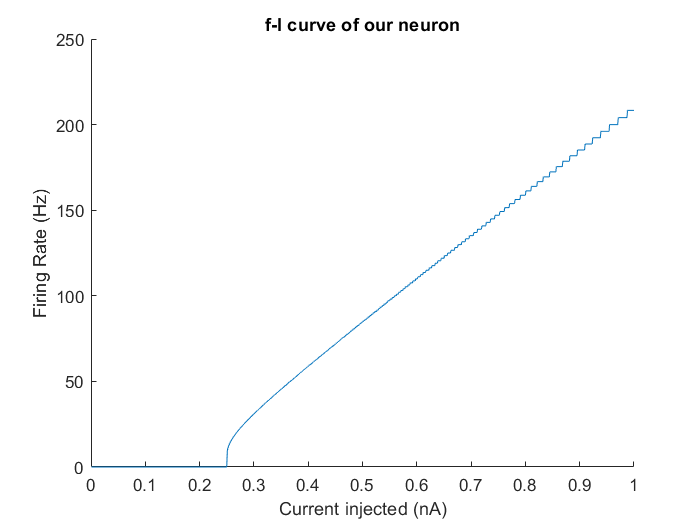

firingrate = zeros(1000);
icurrent = zeros(1000);
for i = 1:1000
    icurrent(i) = .001 * i; %Have incremental steps of current of .001 A
    [V, I, t, spikeTimes] = LIFmodel(icurrent(i)); %Running the LIF Model for each incremental current
    number = length(spikeTimes); %Finding the number of spikes that happens at a given current input
    if number ~= 0
        spikelength = spikeTimes(2) - spikeTimes(1); %Difference in time between each spike
        firingrate(i) = 1000/spikelength; %Inverse of spike time difference gives us the firing rate
    end
end
plot(icurrent, firingrate)
xlabel('Current injected (nA)')
ylabel('Firing Rate (Hz)')
title('f-I curve of our neuron')
box off

The first part of the curve which is entirely horizontal and equal to 0 is when the injected current has not yet allowed the neuron to reach the threshold voltage so there is no spikes. At I = 0.25 nA is the rheobase, where the steady state voltage is equal to the threshold voltage. Then there is a mostly linear increase in the firing rate as a function of injected current, when the steady state voltage is much greater than the reset and threshold voltage, which can be modeled as:


$$f=\frac{1}{C\ast \Delta V}\ast \left(I_e -I_{\mathrm{thr}} \right)$$


9. We can use the above equation to solve for the capacitance:


$$\begin{array}{l}
\text{Slope}=\frac{1}{C∗\Delta V}=270∗{10}^9 \text{ }\frac{\mathrm{Hz}}{A}\\
C=\frac{1}{270∗{10}^9 \text{ }\frac{\text{Hz}}{\text{A}}∗25\text{ }m\mathrm{V}}=\text{ }\ldotp 148\text{ }\text{nF}
\end{array}$$


## Problem 2

- We can use a similar set up as in question 1-8:

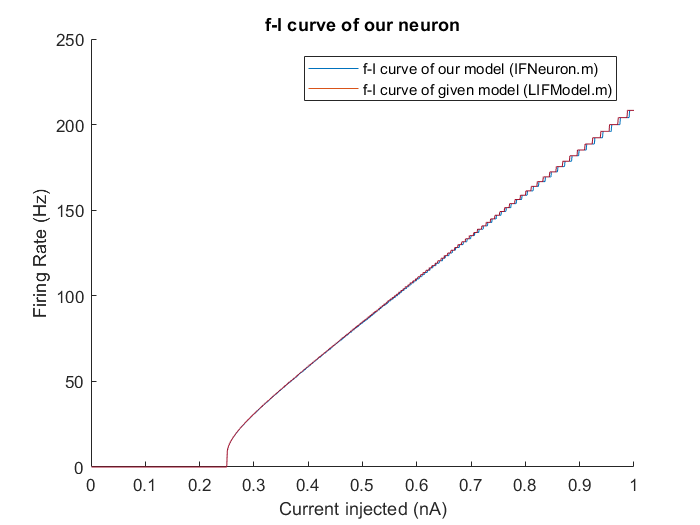

firingrate2 = zeros(1000);
icurrent2 = zeros(1000);
for i = 1:1000
    icurrent2(i) = .001 * i;
    [V2, I2, t2, spikeTimes2] = IFNeuron(icurrent2(i));
    number2 = length(spikeTimes2);
    if number2 ~= 0
        spikelength2 = spikeTimes2(2) - spikeTimes2(1);
        firingrate2(i) = 100/spikelength2;
    end
end
plot(icurrent2, firingrate2)
hold on
plot(icurrent, firingrate)
hold off
xlabel('Current injected (nA)')
ylabel('Firing Rate (Hz)')
title('f-I curve of our neuron')
legend('f-I curve of our model (IFNeuron.m)', 'f-I curve of given model (LIFModel.m)')
box off

2. We can now make code that creates a graph with the two curves overlayed: That is what is shown above, however it is difficult to see, but the two curves are essentially the exact same. There is some variation in the firing rate at the upper part of the given model at higher injected current (some small oscillations) but other than that they are the same. This shows that our parameters that we estimated correspond to the parameters that are input into the LIFModel.m script.

## Problem 3

- We know that the steady state is given as:


$$h_{\infty } =\frac{\alpha_{\infty } }{\alpha_{\infty } +\beta_{\infty } }$$


So we can graph that using the following code:

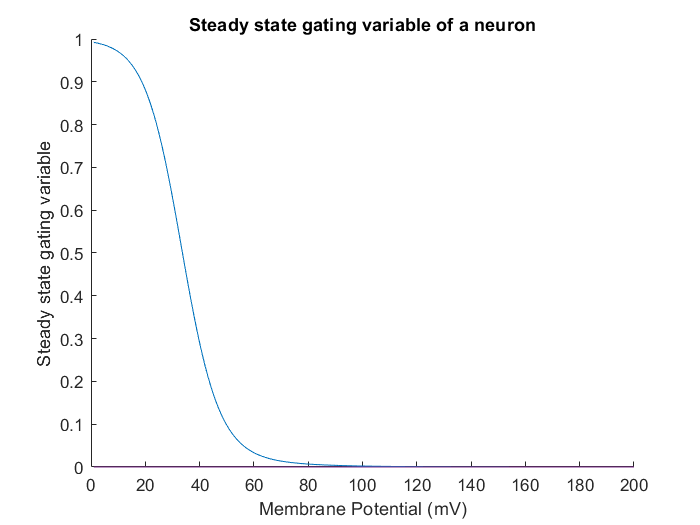

h = zeros(200);
for i = -100:100
    numerator = alphah(i)/2;
    denominator = alphah(i)/2 + betah(i); 
    h(i+101) = (numerator)/(denominator); %Using the above formula to graph h_infinity
end
plot(h)
xlabel('Membrane Potential (mV)');
ylabel('Steady state gating variable');
title('Steady state gating variable of a neuron');
box off

2. We have modified the code and the following graph is produced:

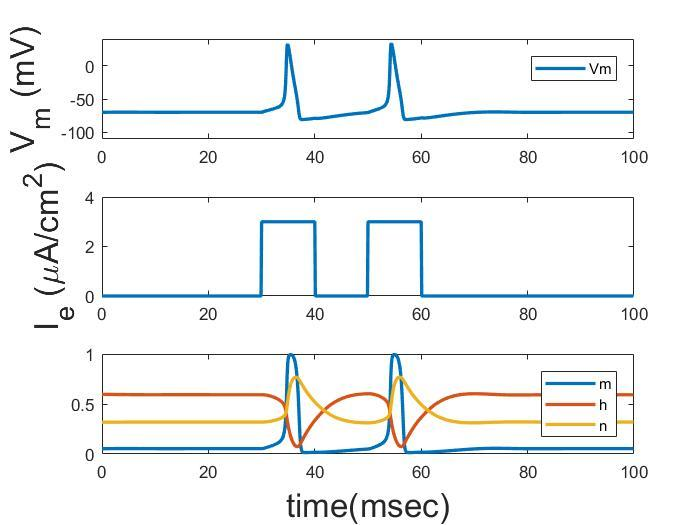

We see that the neuron's membrane potential as well as the values of the gating variables are able to go back to their resting state values in the intermediate time of just 10 ms, to allow for another action potential to occur. This means that our intermediate time of 10 ms is greater than the refractory period.

3. We see the results if there is only a 2 ms pause now:

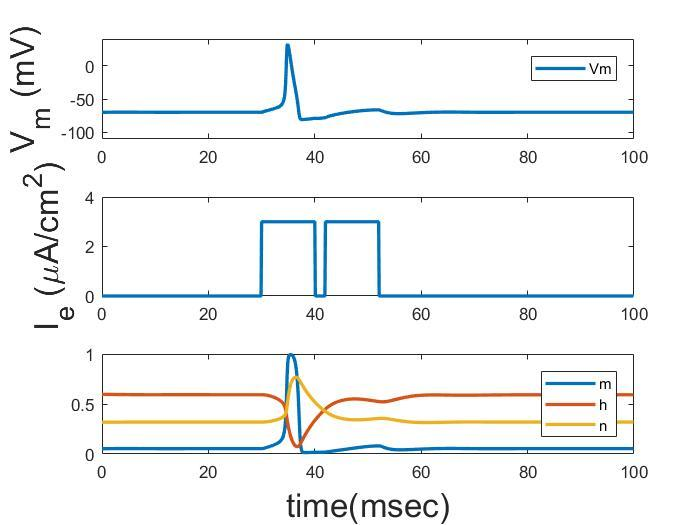

This shows us that the action potential will not stat, even though the current injection may start, since the deinactivation variable has not reached the crtical level to allow the sodium channels to open again and an action potential to occur. This meanas that our intermediate period of 2 ms is likely shorter than the refractory period. 

4. We can calculate the different values using the code below:

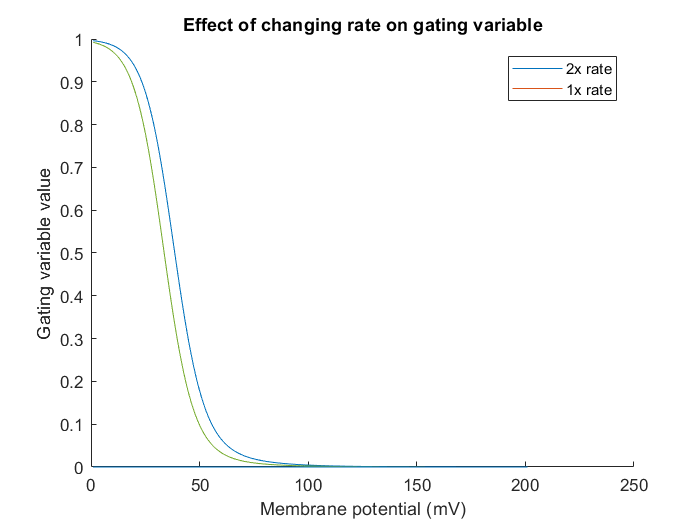

hnew = zeros(200);
hnold = zeros(200);

for i = -100:100
    numeratornew = alphah(i);
    denominatornew = alphah(i) + betah(i);
    hnew(i+101,1) = numeratornew/denominatornew;
end

for j = -100:100
    numerator = alphah(j)/2; %We are dividing by 2 because the alphah.m code is modified to be 2x, so to get the old value of alphah, we divide by 2
    denominator = alphah(j)/2 + betah(j);
    hnold(j+101,1) = numerator/denominator;
end
plot(hnew);
hold on;
plot(hnold);
hold off;
%legend ('show');
legend('2x rate','1x rate');
xlabel('Membrane potential (mV)');
ylabel('Gating variable value')
title('Effect of changing rate on gating variable');
box off

This shows us that the value of the gating variable will increase for all membrane potentials given the increase in the rate. This means that it is easier for the sodium channel to be deinactivated.

5. When we use the modified version of alphah.m what we find is given below:

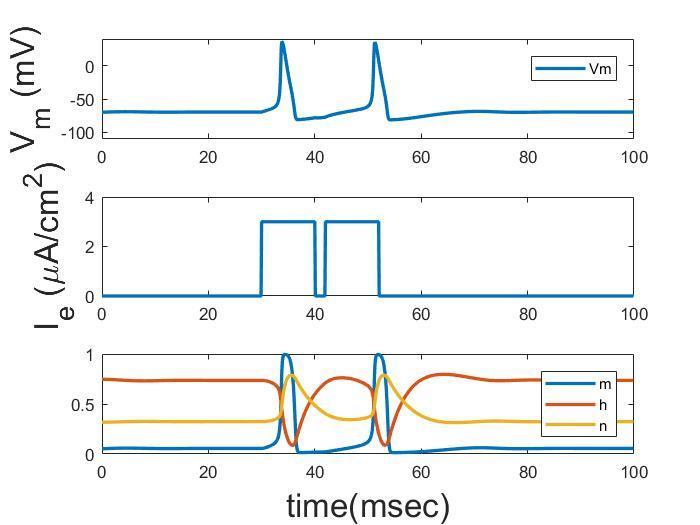

We see that the neuron has overall higher values of h - that is to say that the deinactivation is closer to 1, which means that the sodium channel has a higher probability of being activated. This leads to an action potential now after the second current input, with the 2 ms interval between current inputs, even though in 3.3, there was no action potential, because the sodium channel in general, as we say in the previous part, has a higher chance of being deinactivated. When there is a higher chance of the sodium channel being active/more action potentials, this can lead to a failure to inactivate the channels due to a build up of extracellular potassium ions. This can in turn depolarize the neuron by potassium ion influx, which leads to a positive feedback loop of more potassium ion buildup. This repeated stimulation of the muscle fibers causes myotonic run, indicative of many sodium ion channel disorders.

## Problem 4

- When we modify the code and run HHHyper.m we get the following graph:   

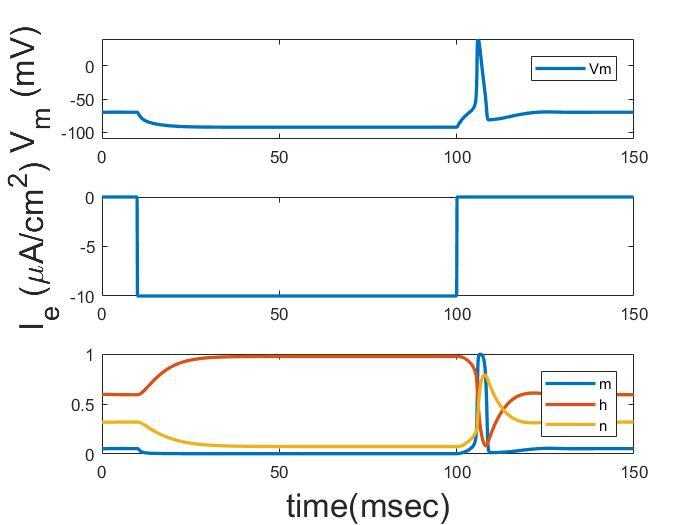

2. When the neuron is hyperpolarized, the gating variables approach their steady state values at hyperpolarization. Due to hyperpolarization, the neuron is not reaching it's threshold because the gating variable 'n' is very low. However, the gating variable 'h' is very high. When the neuron depolarizes, it causes the sodium channels to quickly increase in value even though it takes slightly longer for the deinactivation factor to stop the sodium channel influx. Thus, very briefly, the conductance of the sodium channel is high enough to  cause a depolarization of the neuron and thus an action potential. This is known as the reboundn activity.

3. This would not work in the integrate and fire model since the integrate and fire model does not include the gating variable 'h'. It also will only have an action potential when the neuron reaches a threshold voltage, and not based on the conductance of the different ion channels, which is the main driving force, per se, behind the action potential that we see here.